## PROJECT - GROUP 3

### 1) DATASET 

#### Upload the dataset and get a summary of it

load Alzheimer.mat % Original Dataset

% Dataset is already defined as a table

summary(Dataset);

Variables:

    ID: 174×1 double

        Values:

            Min            1  
            Median      87.5  
            Max          174  

    air_time1: 174×1 double

        Values:

            Min               65
            Median          2890
            Max       1.0996e+05

    disp_index1: 174×1 double

        Values:

            Min       1.68e-06
            Median    9.42e-06
            Max       2.83e-05

    gmrt_in_air1: 174×1 double

        Values:

            Min        28.735 
            Median     255.79 
            Max        1168.3 

    gmrt_on_paper1: 174×1 double

        Values:

            Min        29.936 
            Median     176.49 
            Max        865.21 

    max_x_extension1: 174×1 double

        Values:

            Min          754  
            Median      1681  
            Max        18602  

    max_y_extension1</

#### If possible, transform the variables in categorical and get a summary

% Features are all continuous (not discrete) and possess different scales, the only variable that can be converted into a 
% categorical one is 'class'

Dataset.class = categorical(Dataset.class);
summary(Dataset.class)

     H      85 
     P      89 


#### Remove the unnecessary values

Dataset.ID = [];    % Remove the 'ID' variable (not useful)

#### Check for NaN values and remove them

height1 = height(Dataset);      % height1 is the height of the original Dataset

for column = 1:width(Dataset)-1
    idx = find(isnan(Dataset{:,column})); 
    Dataset(idx,:) = [];
end

height2 = height(Dataset);  % height2 is the height of the Dataset after having removed the possible NaN values

% Check if the height has changed

if height1 == height2
   disp("There isn't any NaN value in the table")
else
   disp("The NaN values have been removed from the table")
end

The NaN values have been removed from the table


clearvars -except Dataset

### 2) VISUALIZATION

#### Define a matrix containing all the indices of the different variables for the 25 tasks

features_indices = zeros(18,25);        % initialize the matrix

for i = 1:18
    features_indices(i,:) = i:18:width(Dataset)-1;
end

features_indices;       % each column represents a task and contains the indices of the 18 features for the relative task

#### Generate 18 figures (one for each variable), each one containing 25 subplots for the different tasks, in order to visualize the features distributions (uncomment to run the code or see the folder named "Subplots").

% for feature = 1:size(features_indices,1)
%     figure
%     for task = 1:size(features_indices,2) 
%         subplot(5,5,task)
%         histogram(Dataset{:,features_indices(feature, task)})
%         title("Subplot " + Dataset.Properties.VariableNames(features_indices(feature, task)))
%     end
% end

### 3) PRE-PROCESSING

#### Inspect all the histograms in order to make a distinction between normal and not normal distributions, so as to select the best way to handle outliers.

% 'G' if the variable distribution is gaussian, "N" if it is not normal

dist = ['N','G','N','N','N','N','N','N','N','N','G','N','N','N','N','N','N','N','N','G','N','N','N','N','N','N','N','N','N','N',...
'N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','G','N','N','N','N','N','N','N','N','N','N','N','N','N',...
'N','N','N','N','N','N','N','N','N','N','N','N','N','N','G','N','N','N','N','N','G','N','N','N','G','N','N','N','N','N',...
'N','N','N','N','N','N','N','N','G','N','N','N','N','N','N','N','N','N','N','N','N','N','G','N','N','N','N','N','N','N',...
'N','N','N','N','G','N','N','N','N','N','N','N','N','G','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N',...
'N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','G','N','N','N','N','N','N','G','N','N','N','N','N','N','N',...
'N','N','N','N','N','N','N','N','G','N','N','N','N','N','N','N','G','N','N','N','N','G','G','N','N','N','N','N','G','N',...
'N','N','N','N','N','N','N','N','N','N','N','N','N','G','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N',...
'N','N','N','N','G','N','G','G','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','G','N','N','N','N','N',...
'N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','G','N','N','N','N','N','N','G','N','N','N',...
'G','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N',...
'N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','G','N','G','N','G','N','N','N','N','N','N','N','N','N','N',...
'N','N','N','N','N','N','N','N','N','N','G','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N',...
'N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N',...
'N','N','N','N','G','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','N','G','N','N','N','N','N','N'];

#### Find the outliers

not_normal = find(dist == 'N');     % not_normal is the vector containing the indices of the variables characterized a by a non normal distribution
gauss = find(dist == 'G');          % gauss is the vector containing the indices of the variables characterized a by a gaussian distribution

M = zeros(174,450);

% Find outliers in the gaussian distributions using the Grubbs method

for i = 1:length(gauss)
    vec_outlG = find(isoutlier(Dataset(:,gauss(i)),"grubbs") == 1);
    for el = 1:length(vec_outlG)
        M(vec_outlG(el),gauss(i)) = 1;
    end
end

% Find outliers in the not-normal distributions using the Quartile method

for i = 1:length(not_normal)
    vec_outlN = find(isoutlier(Dataset(:,not_normal(i)),"quartiles") == 1);
    for el = 1:length(vec_outlN)
        M(vec_outlN(el),not_normal(i)) = 1;
    end
end

% M presents now a value equal to 1 in each cell containing an outlier

% How many observations in the Dataset present outliers?

out = [];

for row = 1:size(M,1)
    for col = 1:size(M,2)
        if M(row,col) == 1
            out = [out row];
        end
    end
end

out = unique(out)     % check if there are some rows in our Dataset free from outliers 

out =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


% Each observation presents at least one outlier --> Remove some outliers
% and winsorize the rest of them

#### Remove outliers from Dataset

% From the subplots we set some common thresholds for the variables in order to remove outliers

% Remove outliers from air_time 1 and 2
airtime1 = features_indices(1,[1 2]);   % it contains the indices of the variable air_time for tasks 1 and 2

for variable = 1:length(airtime1)
    r = find(Dataset{:,airtime1(variable)} > 80000);
    Dataset(r,:) = [];      % Remove all the Dataset rows in which outliers are present
end

% Remove outliers from air_time 17 and 22
airtime2 = features_indices(1,[17 22]);     % it contains the indices of the variable air_time for tasks 17 and 22

for variable = 1:length(airtime2)
    r = find(Dataset{:,airtime2(variable)} > 800000);
    Dataset(r,:) = [];
end

% Remove outliers from max_x_extension 19
r = find(Dataset{:,features_indices(5,19)} > 15000);
Dataset(r,:) = [];

% Remove outliers from max_x_extension 17
r = find(Dataset{:,features_indices(5,17)} < 2000);
Dataset(r,:) = [];

% Remove outliers from max_y_extension 2
r = find(Dataset{:,features_indices(6,2)} > 10000);
Dataset(r,:) = [];

% Remove outliers from mean_gmrt 8 and 12
meanGmrt = features_indices(9,[8 12]);      % it contains the indices of the variable mean_gmrt for tasks 18 and 12

for variable = 1:length(meanGmrt)
    r = find(Dataset{:,meanGmrt(variable)} > 1500);
    Dataset(r,:) = [];
end

% Remove outliers from paper_time 1, 20 and 22
paperTime1 = features_indices(15,[1 20 22]);        % it contains the indices of the variable paper_time for tasks 1, 20 and 22

for variable = 1:length(paperTime1)
    r = find(Dataset{:,paperTime1(variable)} > 40000);
    Dataset(r,:) = [];
end

% Remove outliers from paper_time 17 and 19
paperTime2 = features_indices(15,[17 19]);      % it contains the indices of the variable paper_time for tasks 17 and 19

for variable = 1:length(paperTime2)
    r = find(Dataset{:,paperTime2(variable)} > 80000);
    Dataset(r,:) = [];
end

% Remove outliers from pressure_var 11
r = find(Dataset{:,features_indices(17,11)} > 500000);
Dataset(r,:) = [];

% Remove outliers from total_time 1, 2, 5 and 6
totalTime1 = features_indices(18,[1 2 5 6]);        % it contains the indices of the variable total_time for tasks 1, 2, 5 and 6

for variable = 1:length(totalTime1)
    r = find(Dataset{:,totalTime1(variable)} > 110000);
    Dataset(r,:) = [];
end

% Remove outliers from total_time 11 and 22
totalTime2 = features_indices(18,[11 22]);       % it contains the indices of the variable total_time for tasks 11 and 22

for variable = 1:length(totalTime2)
    r = find(Dataset{:,totalTime2(variable)} > 300000);
    Dataset(r,:) = [];
end

% Remove outliers from total_time 17
r = find(Dataset{:,features_indices(18,17)} > 800000);
Dataset(r,:) = [];

% Remove outliers from total_time 14
r = find(Dataset{:,features_indices(18,14)} > 2500000);
Dataset(r,:) = [];

#### Winsorize the remaining outliers

% For each column in Dataset we calculate the first and third quartile and the interquartile range
% Then, the examples that lie outside of the whiskers are winsorized

for col = 1: width(Dataset)-1
    Q3 = prctile(Dataset{:,col},75);
    Q1 = prctile(Dataset{:,col},25);
    InterQR = iqr(Dataset{:,col});
    for ob = 1:height(Dataset)
        if Dataset{ob,col} > (Q3 + 1.5*InterQR)
            Dataset{ob,col} = (Q3 + 1.5*InterQR);
        elseif Dataset{ob,col} < (Q1 - 1.5*InterQR)
            Dataset{ob,col} = (Q1 - 1.5*InterQR);
        end
    end
end

clearvars -except Dataset features_indices

### 4) DIMENSIONALITY REDUCTION

1- FIRST, WE ARE GOING TO REMOVE SOME COLUMNS USING THE CORRELATION BETWEEN VARIABLES AND THEN WE ARE GOING TO PERFORM THE PCA ON THE ALREADY REDUCED DATASET

#### Visualize all the variables distribution through the scatter plot matrix and check also for correlation between variables

The idea is to search for relationships between variables in each different task (otherwise we would have to work with too many variables and it would be impossible to interpret the results).

Do not run this code (the figures are in the folder named "CorrFigures").

% Scatter plot matrix for each task

% task = 1;

% for features = 1:18:433
%     c = features:features+17;
%     X = Dataset{:,c};
%     figure
%     gplotmatrix(X,[],[],[],[],[],[],'hist')
%     title(['Task ', num2str(task)]);
%     R = corrcoef(X)
%     task = task+1;
% end 


% After having saved all the 25 correlation matrices, we created a struct containing all of them (so that it's easier to
% access to the correlation coefficients)
% s = struct('R1',R1,'R2',R2,'R3',R3,'R4',R4,'R5',R5,'R6',R6,'R7',R7,'R8',R8,'R9',R9,'R10',R10,'R11',R11,'R12',R12,
%           'R13',R13,'R14',R14,'R15',R15,'R16',R16,'R17',R17,'R18',R18,'R19',R19,'R20',R20,'R21',R21,'R22',R22,
%           'R23',R23,'R24',R24,'R25',R25);

load StructCorrMatrix.mat     % this struct was used just to visually see which are the pairs of correlated variables

From a visual inspection, we select for each task the features that can be removed in order to reduce our dataset dimensionality before performing PCA.

#### Update the table and remove the unnecessary variables, starting from the last task (so as not to have indices-related troubles).

Data = Dataset;              % Get a copy of the original dataset

% We use the features_indices matrix in order to access to the indices of the variables to remove for each task

Data(:, features_indices([3 7 9:11 18],end)) = [];                      % task 25
Data(:, features_indices([3:5 10:13 18],end-1)) = [];                   % task 24
Data(:, features_indices([3 4 10 11 13 18],end-2)) = [];                % task 23
Data(:, features_indices([3 4 10:13 18],end-3)) = [];                   % task 22
Data(:, features_indices([3 5 10:13 18],end-4)) = [];                   % task 21
Data(:, features_indices([9:11 13 18],end-5)) = [];                     % task 20
Data(:, features_indices([3 4 10 11 18],end-6)) = [];                   % task 19
Data(:, features_indices([1:3 10 12:14 18],end-7)) = [];                % task 18
Data(:, features_indices([3 7 10:13 18],end-8)) = [];                   % task 17
Data(:, features_indices([2 3 10 11 13 18],end-9)) = [];                % task 16
Data(:, features_indices([3 10 11 13 18],end-10)) = [];                 % task 15
Data(:, features_indices([3 4 10:13 18],end-11)) = [];                  % task 14
Data(:, features_indices([3 10 13 18],end-12)) = [];                    % task 13
Data(:, features_indices([3 10 11 13 18],end-13)) = [];                 % task 12
Data(:, features_indices([3 10 11 13 18],end-14)) = [];                 % task 11
Data(:, features_indices([1 3 10 13 15],end-15)) = [];                  % task 10
Data(:, features_indices([3 10 13 18],end-16)) = [];                    % task 9
Data(:, features_indices([3 10 13 18],end-17)) = [];                    % task 8
Data(:, features_indices([2:4 10 11 13 18],end-18)) = [];               % task 7
Data(:, features_indices([9 10 12 13 18],end-19)) = [];                 % task 6
Data(:, features_indices([2 3 10 13 18],end-20)) = [];                  % task 5
Data(:, features_indices([3 10 11 13 18],end-21)) = [];                 % task 4
Data(:, features_indices([3 10 13],end-22)) = [];                       % task 3
Data(:, features_indices([10 13 14 18],end-23)) = [];                   % task 2
Data(:, features_indices([3 4 10:13 18],end-24)) = [];                  % task 1

clearvars -except Dataset  Data features_indices

**Now, perform PCA on Data** (Data is the dataset that has been reduced using correlation)

% Most of the distributions is not normal, so we use the min-max normalization
D = Data{:,1:end-1};            % take all the columns except for the last one (which contains the class)
mu = mean(D); % Row vector of column (feature) means
r = range(D); % Row vector of column ranges
D = (D - mu)./r; % Scaled matrix

[coeff1,score1,latent1,tsquared,p_explained1,mu] = pca(D);          % perform PCA on D

#### Plot the proportion of variance explained by each principle component and the cumulative variance

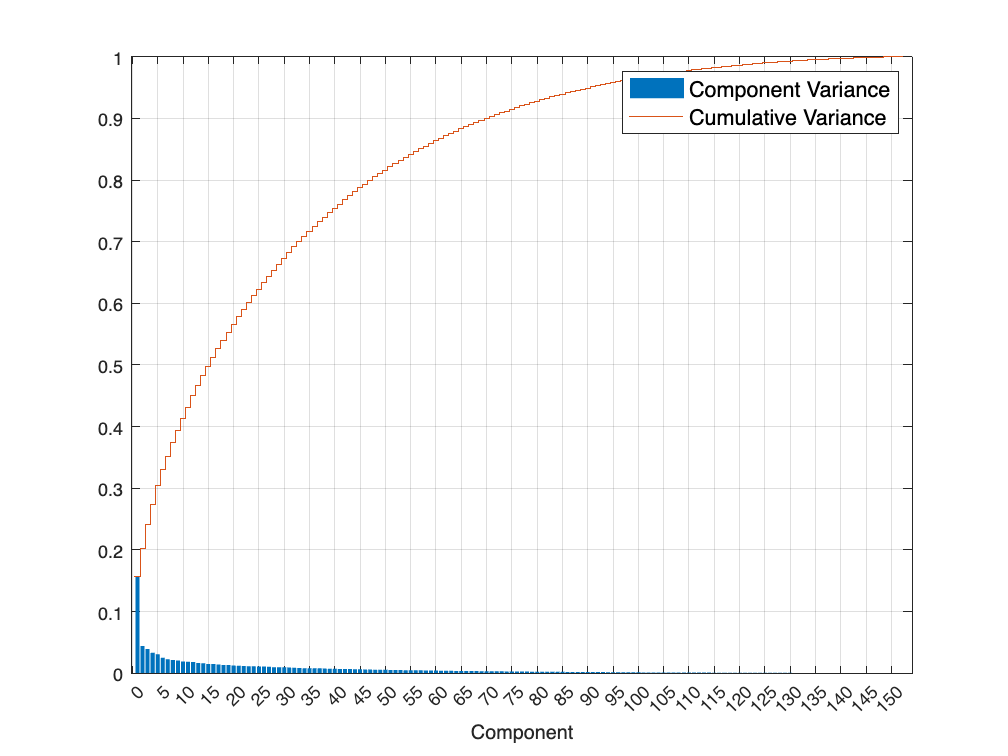

Vnorm = latent1/sum(latent1); % Normalize the variance so the total is 1

figure
hold on
bar(Vnorm);
cumsum(Vnorm);
stairs(0.5:152.5,cumsum(Vnorm))
grid on
box on
hold off
set(gca,'XTick',0:5:152.5)
ylim([0 1])
legend({'Component Variance','Cumulative Variance'},'FontSize',12)
xlabel('Component')

For the next phase (classification), we decide to select the first 56 principal components because the explain approximately the 85% of the cumulative variance.

#### Examine the original feature variances: calculate, sort, and plot the variances of the original (scaled) features for comparison. 

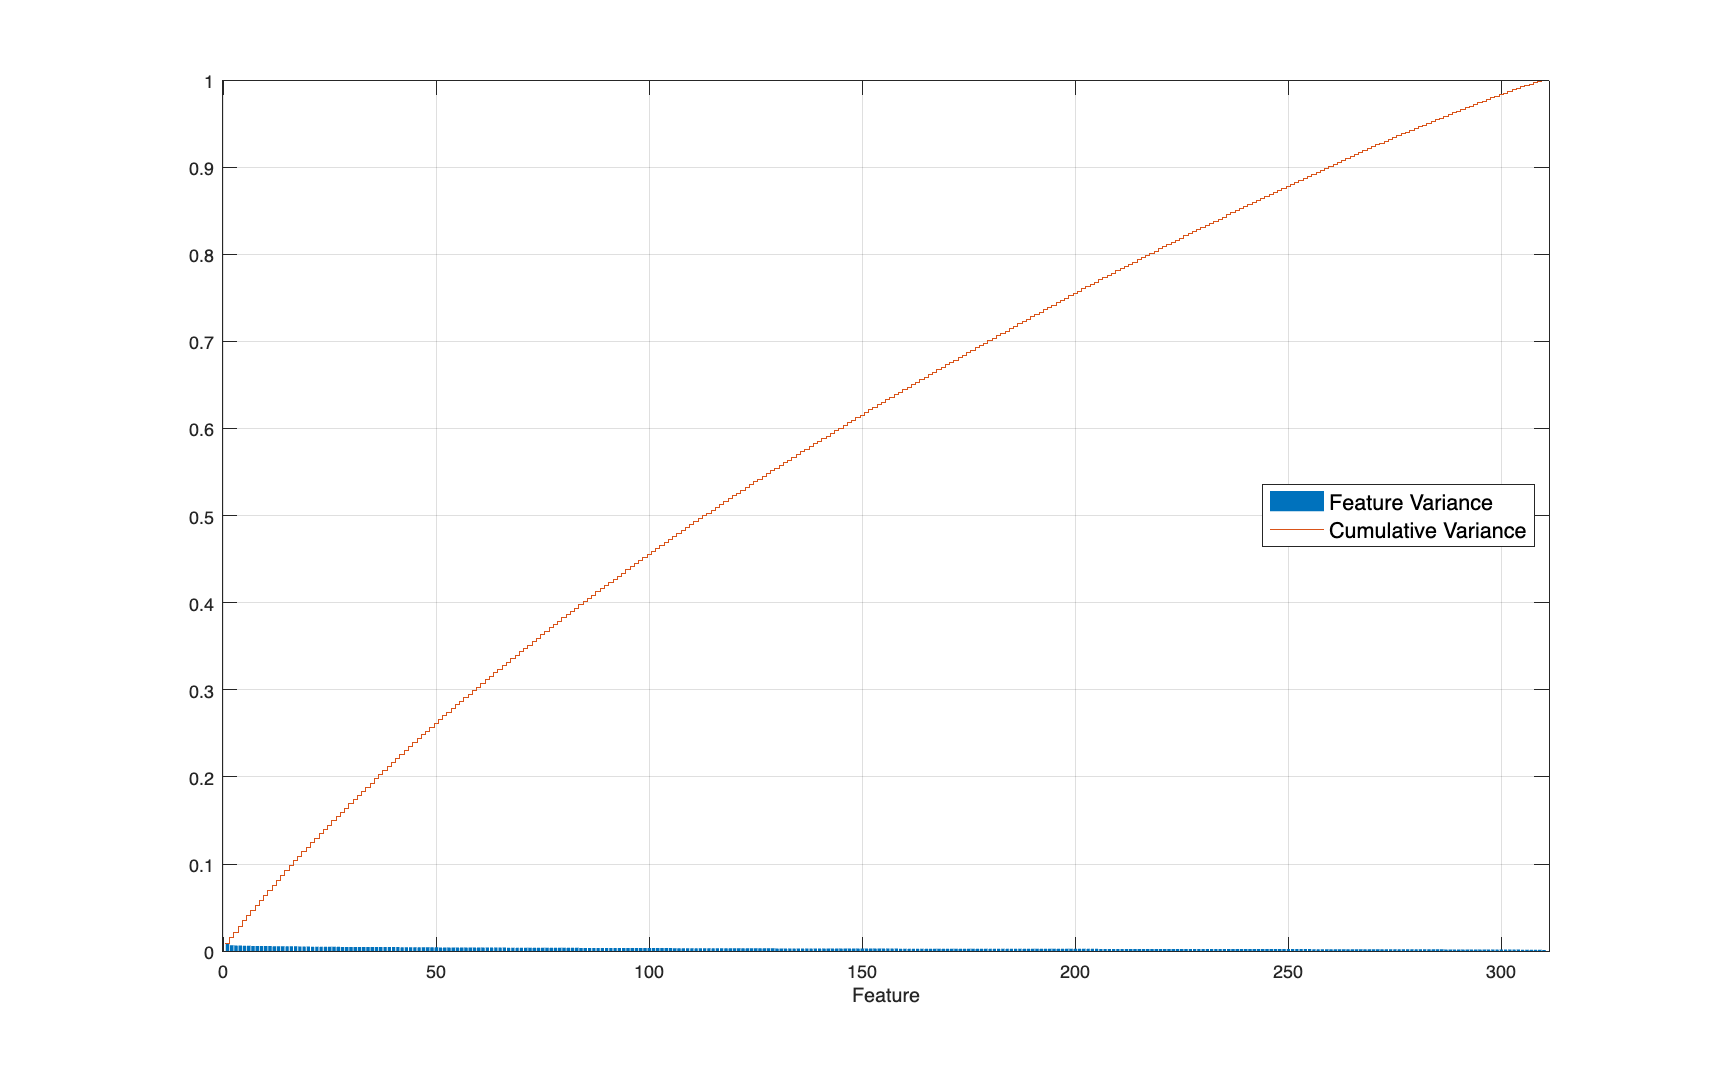

VOrigNorm = var(D);
[VOrigNorm,idx] = sort(VOrigNorm,'descend');
VOrigNorm = VOrigNorm/sum(VOrigNorm); % Normalize the variance so the total is 1

figure
hold on
bar(VOrigNorm);
cumsum(VOrigNorm);
stairs(0.5:309.5,cumsum(VOrigNorm));
grid on; box on; hold off;
set(gcf,'units','normalized','OuterPosition',[0 0 1 1])
legend({'Feature Variance','Cumulative Variance'},'FontSize',12,'Location','east')
xlabel('Feature')
ylim([0,1])

This figure shows that the same amount of variance can be explained by using a number of features that is approximately four times the number of principal components selected before.

The code below uses a heat map to visualize the relationships between the components and features. Rectangles with very light or dark colors indicate a larger contribution by a given feature (row) to a given component (column). Lighter shades indicate negative relationships, darker shades indicate positive relationships.

**NB**: heatmaps are saved in the "Heatmaps" folder (or run the code below).

% The for cycle generates 5 heatmaps for the first 10 principal components
% (we divided the Data observations in 5 groups so as to better visualize the color 
% scale and the relative coefficients)

for c = 1:5
    obs = 1:62:310;

    figure
    heatmap(coeff1(obs(c):obs(c)+61,1:10),'XDisplayLabels',"P"+(1:10),'YDisplayLabels',Data.Properties.VariableNames(obs(c):obs(c)+61),'Title','Component Weights','ColorLimits', [-0.2 0.3]);
    set(gcf,'units','normalized','outerposition',[0 0 1 1])

end

#### After, having chosen the number of principal components that explains approximately 85% of the cumulative variance, we rearrenged the score matrix, adding the feature "class" at the end of it, so as to evaluate the classifier just using the principal components.

NewData1 = [array2table(score1(:,1:56)) Data(:,end)];

2- TO MAKE A COMPARISON, WE ARE NOW GOING TO PERFORM THE PCA ON EACH TASK OF THE ORIGINAL DATASET

% Normalize Dataset
% Most of the distributions is not normal, so we use the min-max normalization

Dataset_norm = Dataset{:,1:end-1};      % take all the columns of Dataset except for the last related to the class
mu = mean(Dataset_norm); % Row vector of column (feature) means
r = range(Dataset_norm); % Row vector of column ranges
Dataset_norm = (Dataset_norm - mu)./r; % Scaled matrix

% Through this for cycle, perform PCA on eact task

for i = 1:size(features_indices,2)
    [coeff2,score2,latent2,tsquared,p_explained2,mu] = pca(Dataset_norm(:,features_indices(:,i)));
    
    Vnorm = latent2/sum(latent2); % Normalize the variance so the total is 1
    figure
    hold on
    bar(Vnorm);
    cumsum(Vnorm);
    stairs(0.5:17.5,cumsum(Vnorm))
    grid on
    box on
    hold off
    set(gca,'XTick',0:5:17.5)
    ylim([0 1])
    legend({'Component Variance','Cumulative Variance'},'FontSize',12)
    xlabel('Component')
    title("Component Variance vs Cumulative Variance for task " + i)

end
% for each task, approximately the 85% of the total variance can be explained by using the first 4 principal components

NewData2 = [];

for i = 1:size(features_indices,2)
    [coeff2,score2,latent2,tsquared,p_explained2,mu] = pca(Dataset_norm(:,features_indices(:,i)));
    
    NewData2 = [NewData2 score2(:,1:4)];

end

% create a new dataset made of the scores of the principal components for each task and then, add the feature "class" at the end

NewData2 = [array2table(NewData2) Dataset(:,end)];  

### 4) CLASSIFICATION, DEVELOP THE MODEL: We're going to test the accuracy of different models

- ORIGINAL DATASET 

#### Split the Dataset in training set and test set

rng(1) % initialize the random number generator with a nonnegative integer seed in order for the result to be reproducible

cv = cvpartition(height(Dataset), "HoldOut", 0.3)  % 70% for training, 30% for testing
datasetTrain = Dataset(cv.training,:); % to train the classifier 
datasetTest = Dataset(cv.test, :); % to test if the model predictions are correct

% check if the two classes are balanced
summary(datasetTrain.class) 
summary(datasetTest.class)

#### Naive Bayes model

mdlNB = fitcnb(datasetTrain,"class",'DistributionNames','kernel')
predicted_class_NB = predict(mdlNB, datasetTest);
[CM, classnames] = confusionmat(datasetTest.class,predicted_class_NB)
confusionchart(CM, classnames)
confusionchart(datasetTest.class,predicted_class_NB,'Title','Class','RowSummary','row-normalized','ColumnSummary','column-normalized');
confusionchart(datasetTest.class,predicted_class_NB,'Title','Class','Normalization','total-normalized');
[t2, a] = cMetrics(datasetTest.class,predicted_class_NB)
evalModelC(datasetTest, mdlNB);

#### Decision Tree model

% First, optimize the hyperparameters

Tree_model = fitctree(datasetTrain,"class",'OptimizeHyperparameters','all');

Tree_model = fitctree(datasetTrain,"class",'MinLeafSize',9,'MaxNumSplits',12,'SplitCriterion','gdi');

% MaxNumSplit = max number of branch nodes
% MinLeafSize = Minimum number of leaf node observations
% gdi = gini's diversity index

y_predict_tree = predict(Tree_model,datasetTest);
[t2, a] = cMetrics(datasetTest.class,y_predict_tree)
evalModelC(datasetTest, Tree_model)

#### SVM model

mdlSVM = fitcsvm(datasetTrain,"class","KernelFunction","linear")
predicted_class_SVM = predict(mdlSVM, datasetTest);
[CM, classnames] = confusionmat(datasetTest.class,predicted_class_SVM)
confusionchart(CM, classnames)
confusionchart(datasetTest.class,predicted_class_SVM,'Title','Class','RowSummary','row-normalized','ColumnSummary','column-normalized');
confusionchart(datasetTest.class,predicted_class_SVM,'Title','Species','Normalization','total-normalized');
[t2, a] = cMetrics(datasetTest.class,predicted_class_SVM)
evalModelC(datasetTest, mdlSVM)

          2. NewData1 (56 Principal Components)

#### Split NewData1 in training/test set

rng(1) % initialize the random number generator with a nonnegative integer seed in order for the result to be reproducible

cv = cvpartition(height(NewData1), "HoldOut", 0.3)  % 30% testing, 70% for training

Train1 = NewData1(cv.training,:); % train the classifier 
Test1 = NewData1(cv.test, :); % test if the model predictions are correct

summary(Train1.class) 
summary(Test1.class)

#### Naive Bayes model

mdlNB1 = fitcnb(Train1,"class")
predicted_class_NB1 = predict(mdlNB1, Test1);
[CM, classnames] = confusionmat(Test1.class,predicted_class_NB1)
confusionchart(CM, classnames)
confusionchart(Test1.class,predicted_class_NB1,'Title','Class','RowSummary','row-normalized','ColumnSummary','column-normalized');
confusionchart(Test1.class,predicted_class_NB1,'Title','Class','Normalization','total-normalized');
[t2, a] = cMetrics(Test1.class,predicted_class_NB1)
evalModelC(Test1, mdlNB1)

#### Decision Tree model

% Optimize the hyperparameters

Tree_model1 = fitctree(Train1,"class",'OptimizeHyperparameters','all');

Tree_model1 = fitctree(Train1,"class",'MinLeafSize',2,'MaxNumSplits',5,'SplitCriterion','deviance');
y_predict_tree1 = predict(Tree_model1,Test1);
[t2, a] = cMetrics(Test1.class,y_predict_tree1)
evalModelC(Test1, Tree_model1)

#### SVM model

mdlSVM1 = fitcsvm(Train1,"class")
predicted_class_SVM1 = predict(mdlSVM1, Test1);
[CM, classnames] = confusionmat(Test1.class,predicted_class_SVM1)
confusionchart(CM, classnames)
confusionchart(Test1.class,predicted_class_SVM1,'Title','Class','RowSummary','row-normalized','ColumnSummary','column-normalized');
confusionchart(Test1.class,predicted_class_SVM1,'Title','Class','Normalization','total-normalized');
[t2, a] = cMetrics(Test1.class,predicted_class_SVM1)
evalModelC(Test1, mdlSVM1)

  2. NewData2 (4 Principal Components for each task)

#### Split NewData2 in training/test set

rng(1) % initialize the random number generator with a nonnegative integer seed in order for the result to be reproducible

cv = cvpartition(height(NewData2), "HoldOut", 0.3)  % 30% testing, 70% for training
Train2 = NewData2(cv.training,:); % train the classifier 
Test2 = NewData2(cv.test, :); % test if the model predictions are correct

summary(Train2.class) 
summary(Test2.class)

#### Naive Bayes model

mdlNB2 = fitcnb(Train2,"class")
predicted_class_NB2 = predict(mdlNB2, Test2);
[CM, classnames] = confusionmat(Test2.class,predicted_class_NB2)
confusionchart(CM, classnames)
confusionchart(Test2.class,predicted_class_NB2,'Title','Class','RowSummary','row-normalized','ColumnSummary','column-normalized');
confusionchart(Test2.class,predicted_class_NB2,'Title','Class','Normalization','total-normalized');
[t2, a] = cMetrics(Test2.class,predicted_class_NB2)
evalModelC(Test2, mdlNB2)

#### Decision Tree model

% Optimize the hyperparameters

Tree_model2 = fitctree(Train2,"class",'OptimizeHyperparameters','all');

Tree_model2 = fitctree(Train2,"class",'MinLeafSize',6,'MaxNumSplits',5,'SplitCriterion','gdi');
y_predict_tree2 = predict(Tree_model2,Test2);
[t2, a] = cMetrics(Test2.class,y_predict_tree2)
evalModelC(Test2, Tree_model2)

#### SVM model

mdlSVM2 = fitcsvm(Train2,"class")
predicted_class_SVM2 = predict(mdlSVM2, Test2);
[CM, classnames] = confusionmat(Test2.class,predicted_class_SVM2)
confusionchart(CM, classnames)
confusionchart(Test2.class,predicted_class_SVM2,'Title','Class','RowSummary','row-normalized','ColumnSummary','column-normalized');
confusionchart(Test2.class,predicted_class_SVM2,'Title','Class','Normalization','total-normalized');
[t2, a] = cMetrics(Test2.class,predicted_class_SVM2)
evalModelC(Test2, mdlSVM2)

% After classification, the results obtained by using the 56 principal components of NewData1 are good, so we proceed 
% extracting the important features from the matrix coeff1, setting a limit for both positive and negative contributions

impfeat = [];       % initialize the vector that will contain the name of the important features

for PC = 1:10
    for variable = 1:310
        if coeff1(variable,PC) >= 0.15
            impfeat = [impfeat Data.Properties.VariableNames(variable)];
        elseif coeff1(variable,PC) <= -0.15
            impfeat = [impfeat Data.Properties.VariableNames(variable)];
        end
    end
end

impfeat = unique(impfeat) % each element is taken just one time (no repetitions of the same variable)

### 5- REGRESSION PROBLEM

Aim: predict gmrt_on_paper1.

% Prediction using all the features from task 1

task1 = array2table(Dataset_norm(:,1:18));      % take the first task from the normalized Dataset
task1.Properties.VariableNames(1:18) = Dataset.Properties.VariableNames(1:18);      % Assign the correct name to each variable
task1 = movevars(task1, "gmrt_on_paper1", "After","total_time1")        % put gmrt_on_paper1 at the end of the table
X = task1{:,1:end-1};       % matrix of predictors
y = task1{:,end};       % feature to predict
rng(1)      % to have a reproducible result
cv = cvpartition(size(X, 1), 'HoldOut', 0.3);       % split X and y in training set and test set
XTrain = X(training(cv), :);
yTrain = y(training(cv), :);
XTest = X(test(cv), :);
yTest = y(test(cv), :);
svmModel = fitrsvm(XTrain, yTrain);     % model using svm
yPred = predict(svmModel, XTest);
t = rMetrics(yTest,yPred)           % calculate metrics for regression 
evalModelR(svmModel,X,y)        % assess the model performance

% Prediction using all the variables for both task1 and task2

t2 = array2table(Dataset_norm(:,1:36));
t2.Properties.VariableNames(1:36) = Dataset.Properties.VariableNames(1:36);
t2 = movevars(t2,"gmrt_on_paper1","After","total_time2")
X = t2{:,1:end-1};
y = t2{:,end};
rng(1)
cv = cvpartition(size(X, 1), 'HoldOut', 0.3);
XTrain = X(training(cv), :);
yTrain = y(training(cv), :);
XTest = X(test(cv), :);
yTest = y(test(cv), :);
svmModel = fitrsvm(XTrain, yTrain);
yPred = predict(svmModel, XTest);
t = rMetrics(yTest,yPred)
evalModelR(svmModel,X,y)

% Prediction using all the variables from task1 to task4

t4 = array2table(Dataset_norm(:,1:72));
t4.Properties.VariableNames(1:72) = Dataset.Properties.VariableNames(1:72);
t4 = movevars(t4,"gmrt_on_paper1","After","total_time4")
X = t4{:,1:end-1};
y = t4{:,end};
rng(1)
cv = cvpartition(size(X, 1), 'HoldOut', 0.3);
XTrain = X(training(cv), :);
yTrain = y(training(cv), :);
XTest = X(test(cv), :);
yTest = y(test(cv), :);
svmModel = fitrsvm(XTrain, yTrain);
yPred = predict(svmModel, XTest);
t = rMetrics(yTest,yPred)
evalModelR(svmModel,X,y)

% Prediction using all the 25 tasks

t25 = array2table(Dataset_norm(:,1:450));
t25.Properties.VariableNames(1:450) = Dataset.Properties.VariableNames(1:450);
t25 = movevars(t25,"gmrt_on_paper1","After","total_time2")
X = t25{:,1:end-1};
y = t25{:,end};
rng(1)
cv = cvpartition(size(X, 1), 'HoldOut', 0.3);
XTrain = X(training(cv), :);
yTrain = y(training(cv), :);
XTest = X(test(cv), :);
yTest = y(test(cv), :);
svmModel = fitrsvm(XTrain, yTrain);
yPred = predict(svmModel, XTest);
t = rMetrics(yTest,yPred)
evalModelR(svmModel,X,y)

% Now predict gmrt_on_paper1 using just the same feature (gmrt_on_paper) for all the 25 tasks

t1 =array2table(Dataset_norm(:,[features_indices(4,2:end) 4]));
t1.Properties.VariableNames(1:25) = Dataset.Properties.VariableNames([features_indices(4,2:end) 4])
X = t1{:,1:end-1};
y = t1{:,end};
rng(1)
cv = cvpartition(size(X, 1), 'HoldOut', 0.3);
XTrain = X(training(cv), :);
yTrain = y(training(cv), :);
XTest = X(test(cv), :);
yTest = y(test(cv), :);
svmModel = fitrsvm(XTrain, yTrain);
yPred = predict(svmModel, XTest);
t = rMetrics(yTest,yPred)
evalModelR(svmModel,X,y)

% task1 is cathegorized as a "Memory and Dictation task"
% Predict gmrt_on_paper1 using all the variables for task1, adding the gmrt_on_paper for the same type of task

tM = array2table(Dataset_norm(:,[1:18 238 310 346 400]));
tM.Properties.VariableNames(1:22) = Dataset.Properties.VariableNames([1:18 238 310 346 400]);
tM = movevars(tM, "gmrt_on_paper1", "After","gmrt_on_paper23")
X = tM{:,1:end-1};
y = tM{:,end};
rng(1)
cv = cvpartition(size(X, 1), 'HoldOut', 0.3);
XTrain = X(training(cv), :);
yTrain = y(training(cv), :);
XTest = X(test(cv), :);
yTest = y(test(cv), :);
svmModel = fitrsvm(XTrain, yTrain);
yPred = predict(svmModel, XTest);
t = rMetrics(yTest,yPred)
evalModelR(svmModel,X,y)

The code below is just to validate the result above (obtained by referring to the type of task).

% task2 is cathegorized as "Graphic"
% Predict gmrt_on_paper2 using all the variables for task2, adding the gmrt_on_paper for the same type of task

tG = array2table(Dataset_norm(:,[19:36 features_indices(4,[3:5 21 24])]));
tG.Properties.VariableNames(1:23) = Dataset.Properties.VariableNames([19:36 features_indices(4,[3:5 21 24])]);
tG = movevars(tG, "gmrt_on_paper2", "After","gmrt_on_paper24")
X = tG{:,1:end-1};
y = tG{:,end};
rng(1)
cv = cvpartition(size(X, 1), 'HoldOut', 0.3);
XTrain = X(training(cv), :);
yTrain = y(training(cv), :);
XTest = X(test(cv), :);
yTest = y(test(cv), :);
svmModel = fitrsvm(XTrain, yTrain);
yPred = predict(svmModel, XTest);
t = rMetrics(yTest,yPred)
evalModelR(svmModel,X,y)

% task6 is cathegorized as "Copy"
% Predict gmrt_on_paper6 using all the variables for task6, adding the gmrt_on_paper for the same type of task

tC = array2table(Dataset_norm(:,[features_indices(:,6)' features_indices(4,[7:13 15:17 19 22 25])]));
tC.Properties.VariableNames(1:31) = Dataset.Properties.VariableNames([features_indices(:,6)' features_indices(4,[7:13 15:17 19 22 25])]);
tC = movevars(tC, "gmrt_on_paper6", "After","gmrt_on_paper25")
X = tC{:,1:end-1};
y = tC{:,end};
rng(1)
cv = cvpartition(size(X, 1), 'HoldOut', 0.3);
XTrain = X(training(cv), :);
yTrain = y(training(cv), :);
XTest = X(test(cv), :);
yTest = y(test(cv), :);
svmModel = fitrsvm(XTrain, yTrain);
yPred = predict(svmModel, XTest);
t = rMetrics(yTest,yPred)
evalModelR(svmModel,X,y)

### 6) STATISTICAL ANALYSIS

% Check if data have normal distribution through the adtest() function

variables = 1;
[h,p] = adtest(Data{:,variables})

% In general, the variables have non-normal distributions so a non-parametric test must be used

Plot the variables to transform into categorical, in order to choose the intervals for their discretization.

% Plot mean_gmrt12
plot(Data{:,152})
title("mean_gmrt12")

% Plot paper_time4
plot(Data{:,51})
title("paper_time4")

% Plot mean_acc_on_paper4
plot(Data{:,47})
title("mean_acc_on_paper4")

% Plot num_of_pendown8
plot(Data{:,101})
title("num_of_pendown8")

Discretize the four variables

% Discretize mean_gmrt12
x = Data.mean_gmrt12;
catn = ["LowT", "NormalT", "HighT"];
Data.mean_gmrt12 = discretize(x,[0 150 300 500], 'categorical',catn);

% Discretize paper_time4
x = Data.paper_time4;
catn = ["FewTime", "NormalTime", "MuchTime"];
Data.paper_time4 = discretize(x,[0 20000 35000 60000], 'categorical',catn);

% Discretize mean_acc_on_paper4
x = Data.mean_acc_on_paper4;
catn = ["Slow", "Normal", "Fast"];
Data.mean_acc_on_paper4 = discretize(x,[0 0.1 0.2 0.3], 'categorical',catn);

% Disretize num_of_pendown8
x = Data.num_of_pendown8;
catn = ["Normal", "Many", "TooMany"];
Data.num_of_pendown8 = discretize(x,[0 1.5 2.5 3.5], 'categorical',catn);

% Create a table containing just the categorical variables that have just been transformed
catvar = [Data(:,51) Data(:,152) Data(:,47) Data(:,101)];

X = Data;         % Get a copy of Data

% Remove from X the categorical variables and maintain just the numerical ones
X = removevars(X,[X.Properties.VariableNames([51 152 47 101])]);    

Through a for cycle, check if the categorical variables (each at a time)  have a significant effect on the remaining numerical ones.

% Run kruskalwallis test, with a significance level of 5%

for cat = 1:width(catvar)
    sigeff = [];        % significant effect vector
    fact = catvar.Properties.VariableNames(cat);
    for col = 1:width(X)-1
        p = kruskalwallis(X{:,col},catvar{:,cat},'off');
        if p < 0.05             
            sigeff = [sigeff; X.Properties.VariableNames(col)];   % the vector contains the list of numerical variables for which the test returns a p-value lower than 5%
        end  
    end
    disp(fact + "has a significant effect on " + sigeff)
end

Analyze now how each categorical variable affects a numerical one of the same task, choosen in the list displayed above.

% Effect of num_of_pendown8 on gmrt_on_paper8
[p,tbl,stats] = kruskalwallis(X.gmrt_on_paper8,catvar.num_of_pendown8,'off')
% Run the multiple comparison test
multcompare(stats)
title("GmrtOnPaper8 vs NumOfPendown8")
% Effect of mean_gmrt12 on max_x_extension12
[p,tbl,stats] = kruskalwallis(X.max_x_extension12,catvar.mean_gmrt12,'off')
% Run the multiple comparison test
multcompare(stats)
title("MaxXExtension12 vs MeanGmrt12")
% Effect of mean_acc_on_paper4 on gmrt_on_paper4
[p,tbl,stats] = kruskalwallis(X.gmrt_on_paper4,catvar.mean_acc_on_paper4,'off')
% Run the multiple comparison test
multcompare(stats)
title("GmrtOnPaper4 vs MeanAccOnPaper4")
% Effect of paper_time4 on num_of_pendown4
[p,tbl,stats] = kruskalwallis(X.num_of_pendown4,catvar.paper_time4,'off')
% Run the multiple comparison test
multcompare(stats)
title("NumOfPendown4 vs PaperTime4")

#### Functions to use

Evaluate the model - Regression

function evalModelR(mdl,X,y)
    disp("Training Error: " + resubLoss(mdl))
    disp("Loss: " + loss(mdl,X,y))
end

Evaluate the model - Classification

function evalModelC(dataTest, mdl)
    disp("Training Error: " + resubLoss(mdl))
    disp("Loss: " + loss(mdl,dataTest))
end   